x1 = [1 2 3 4 5];
x2 = [1.1 2.2 3.3 4.4 5.5];
x = [x1,x2]';
y1 = [4 5 6 7 8];
y2 = [4.2 5.2 6.2 7.8 8.9];
y = [y1,y2]';

gprMd_bau_top = fitrgp(x,y);
bre_pred_top = resubPredict(gprMd_bau_top);

[X,Y,Z] = meshgrid(x1,x2,y1);
plot3(x1,x2,bre_pred_top,'*')
p = predict(gprMd_bau_top,1.1)

fused = (x1*var(x1)^-1 + x2*var(x2)^-1)/(var(x1)^-1+var(x2)^-1)
plot(x1,y1,'*'); hold on
plot(x2,y1,'*'); hold on
plot(fused, y1,'--'); hold off

cd 'H:\deep_learning_images'
data = importdata("test_gpr_data.txt");
new_data = (data(:,1)*var(data(:,1))+data(:,2)*var(data(:,2))+data(:,3)*var(data(:,3))+data(:,4)*var(data(:,4)))/...
    (var(data(:,1))+var(data(:,2))+var(data(:,3))+var(data(:,4)));
height = 0:1:10;
gpr = fitrgp(new_data,height);
pred_height = resubPredict(gpr)

pred_height =     0.0626
    1.1922
    1.6483
    3.1147
    4.0119
    4.9729
    5.9587
    6.9520
    8.1807
    9.1163


load_gpr = importdata("gpr_model.mat");
pred_height_from_load_gpr = predict(load_gpr,bren_sharp_bot')
plot(bren_sharp_bot',norm_height_b_bot,'-r*'); hold on
plot(bren_sharp_bot',pred_height_from_load_gpr,'--bo'); hold off
legend('experimental data','prediction');

h = 2
t=norm_height_b_bot(1:h);
n = numel(t);

% state matrix
X = zeros(2,1);

% covariance matrix
P = zeros(2,2);

% kalman filter output through the whole time
X_arr = zeros(n, 2);

% system noise
Q = [rand(1) 0;
    0 rand(1)];

% transition matrix
dt = 1;

F = [1 dt;
    0 1];

% observation matrix
H = [1 0];

% variance of signal 1

s1 = generate_signal(bren_sharp_bot(1:h), var(bren_sharp_bot(1:h)));

% variance of signal 2

s2 = generate_signal(gau_sharp_bot(1:h), var(gau_sharp_bot(1:h)));


% fusion
for i = 1:n
    if (i == 1)
        [X, P] = init_kalman(X, s1(i, 1)); % initialize the state using the 1st sensor
    else
        [X, P] = prediction(X, P, Q, F);

        [X, P] = update(X, P, s1(i, 1), s1(i, 2), H);
        [X, P] = update(X, P, s2(i, 1), s2(i, 2), H);
    end

    X_arr(i, :) = X;
end

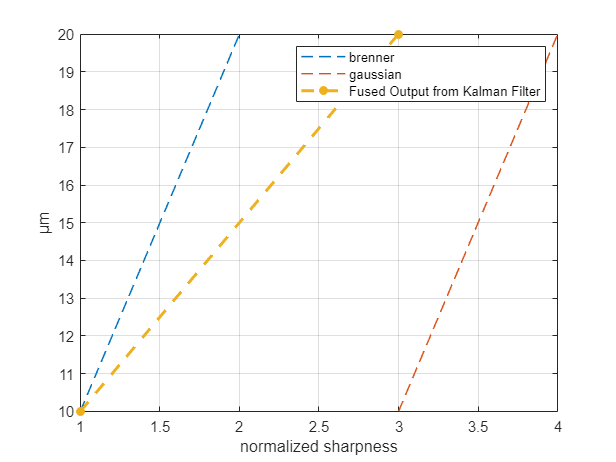



plot(s1(:, 1),t, '--', 'LineWidth', 1); hold on;
plot(s2(:, 1),t, '--', 'LineWidth', 1);
plot(X_arr(:, 1),t, '--*','LineWidth', 2);
hold off;
grid on;
legend('brenner', 'gaussian', 'Fused Output from Kalman Filter');
xlabel('normalized sharpness')
ylabel('\mum')

function [s] = generate_signal(signal, var)
s(:, 1) = signal;
s(:, 2) = var;
end

function [X, P] = init_kalman(X, y)
X(1,1) = y;
X(2,1) = 0;

P = [100 0;
    0   300];
end

function [X, P] = prediction(X, P, Q, F)
X = F*X;
P = F*P*F' + Q;
end

function [X, P] = update(X, P, y, R, H)
Inn = y - H*X;
S = H*P*H' + R;
K = P*H'/S;

X = X + K*Inn;
P = P - K*H*P;
end

% plot(x,y,'*'); hold on
% plot(x1, bre_pred_top,'--b*'); hold on
% plot(x2,bre_pred_top,'r--.'); hold off
